# Worksheet 3

We now reconsider the two ODEs from worksheet 2 but with different parameters

For **Dahlquist’s test equation** we now consider $\lambda  = -7$ such that we get:

$ẋ = (-7)x$    (1)

with initial condition

$x(0) = 1$    (2)

The analytical solution is then given by


$$x(t) = e^ {-7t}$$


**a)** Reuse the Euler method implemented in worksheet 2 to compute approximate solutions for equation (1) with initial condition (2), end time $t_{end} = 5$, and $\delta t = \frac{1}{2}, \frac{1}{4}, \frac{1}{8}, \frac{1}{16}, \frac{1}{32}$.

Plot your solutions for $t \in  [0, 5]$ in one figure together with the analytical solution.

Plot only in the range $x \in  [-1, 1].$

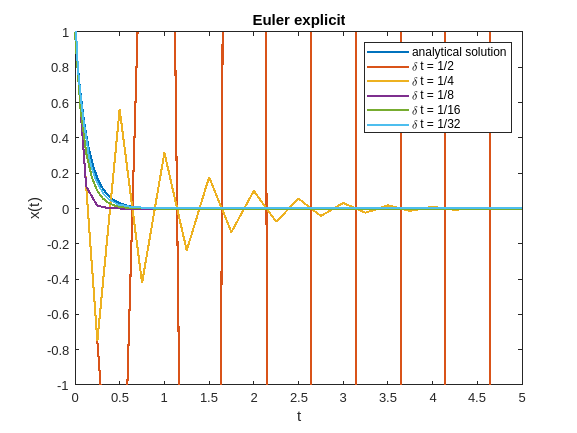

format shortG
lambda = -7;
f = @(x) lambda*x;
x_0 = 1;
x = @(t) exp(lambda*t);
t_end = 5;
t = linspace(0,5);
figure
plot(t,x(t), 'linewidth', 1.5);
hold on
i = 1;
for dt = 2.^-(1:5)
    y = expl_euler(x_0, dt, t_end, f);
    plot(0:dt:t_end,y, 'linewidth', 1.5);
    approx_err_expl(i) = approx_error(dt, t_end, y, x(0:dt:t_end));
    i = i+1;
end
hold off
title ('Euler explicit')
legend('analytical solution', '\delta t = 1/2', '\delta t = 1/4', '\delta t = 1/8', '\delta t = 1/16', '\delta t = 1/32')
xlabel('t')
ylabel('x(t)')
ylim([-1,1])

**b)** We will now implement the implicit Euler method. As a first step, implement the

Newton method to solve a nonlinear equation $\mathcal{G}(a) = 0$. The update step for the Newton iteration reads:

$a^{n+1}= a^n - D\mathcal{G}(a^n)^{-1}f(a^n)$.

Calculate the derivative analytically and pass the function handle as an argument to the Newton solver, i.e.: 

`function y = newton(x 0, G, dG).`

As stopping criteria for the method use a maximum number of iterations of 100 and accuracy of $\varepsilon  = 10^{-8}$.

**Hint:** To make sure your implementation works properly, you may test it with this problem: find the root of $x^3 - 3$. Start at $x_0 = 1$.

*(N.B. implementation in a separate file)*

`function x=newton(x_0, G, dG)`

`maxI=100;`

`minEps=10e-8;`

`i=0;`

`epsilon=inf;`

`while(i<maxI && epsilon>minEps)`

`    x=x_0-G(x_0)./dG(x_0);`

`    epsilon=abs(x-x_0)./max(abs(x),1);`

`    x_0=x;`

`    i=i+1;`

`end`

`end`

x_0 = 1;
g = @(x) x.^3-3;
dg = @(x) 3*x^2;
x = newton(x_0, g, dg)

x =        1.4422


**c)** Use the Newton method to implement the implicit Euler method with variable step size $\delta t$ and end time $t_{end}$ for the solution of the initial value problem

$ẏ = f (y)$,    $y(0) = y_0$

as a function of the initial value $y_0$ , the time step size $\delta t$, the end time $t_{end}$, the right hand side $f(y)$, and the first derivative of the right hand side with respect to $y$, i.e.:

`function y = impl_euler(y 0, dt, t end, f, df)`

The output of the function is a vector containing all approximate values for $y$, including $y_0$ .

**Hints:**

- The update scheme of the implicit Euler reads $y^{n+1} = y^n + \delta t  \cdot f (y^{ n+1} )$. How do you map this to a root finding problem?

- Examine if the equation to be solved in each time step is solvable. If not, stop the time stepping with the method and the time step concerned and do not consider the associated approximations of $y$ in your further examinations.

*(N.B. implementation in a separate file)*

`function y = impl_euler(y_0, dt, t_end, f, df)`

`t = 0:dt:t_end;`

`y = zeros(1,length(t));`

`y(1) = y_0;`

`dG = @(x) dt*df(x)-1;`

`for i=1:length(y)-1`

`    G = @(x) dt*f(x)-x+y(i);`

`    y(i+1) = newton(y(i), G, dG);`

`end`

`end`

**d) **Compute – as far as possible – approximate solutions for equation (1) with initial conditions (2) and with time steps $\delta t = \frac{1}{2}, \frac{1}{4}, \frac{1}{8}, \frac{1}{16}, \frac{1}{32}$. Plot your solutions for $t \in  [0, 5]$ in one graph together with the analytical solution. Plot only in the range $x \in  [-1, 1]$.

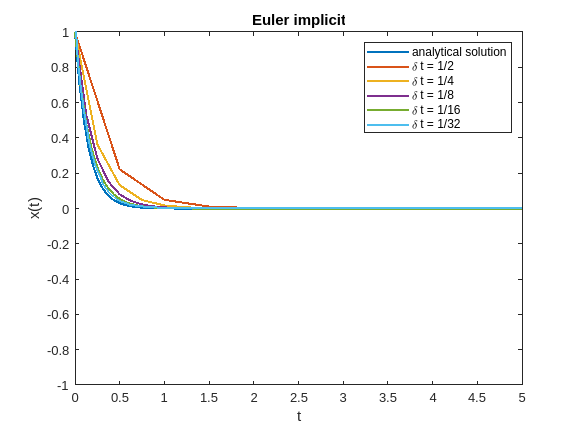

lambda = -7;
f = @(x) lambda*x;
df = @(x) lambda;
x_0 = 1;
x = @(t) exp(lambda*t);
t_end = 5;
figure
plot(t,x(t), 'linewidth', 1.5);
hold on
i = 1;
for dt = 2.^-(1:5)
    y = impl_euler(x_0, dt, t_end, f, df);
    plot(0:dt:t_end,y, 'linewidth', 1.5);
    approx_err_impl(i) = approx_error(dt, t_end, y, x(0:dt:t_end));
    i = i+1;
end
hold off
title ('Euler implicit')
legend('analytical solution', '\delta t = 1/2', '\delta t = 1/4', '\delta t = 1/8', '\delta t = 1/16', '\delta t = 1/32')
xlabel('t')
ylabel('x(t)')
ylim([-1,1])

**e)** To compare the results of the implicit method to those of the explicit method, we compute again the approximation error


$$E = \sqrt{\frac{\delta t}{t_{end}}\sum_{k} (x_k - x_{k, exact})^2}$$


for each case, where $x_k$ denotes the approximation of $x(\delta t\cdot k)$ and $x_{exact,k}$ the exact values of $x$ at $t = \delta t \cdot  k$. Additionally, determine the factor by which the error is reduced if the step size $\delta t$ is halved.

Collect the results in the tables below. Also write all information needed in the tables to the MATLAB console in a readable way.

**Hint: **The reduction factor should be greater than one if the error is reduced.

*(N.B. implemented in a separate file)*

`function e = approx_error(dt, t_end, x, x_exact)`

`e = sqrt(dt/t_end*sum((x-x_exact).^2));`

`end`

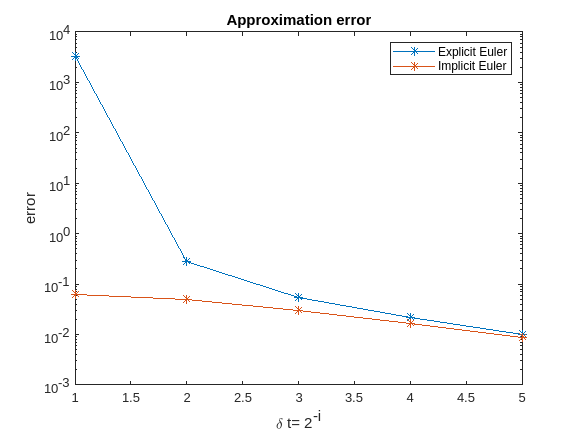

figure
dt = 1:5;
semilogy(dt,approx_err_expl,'-*')
hold on
semilogy(dt,approx_err_impl, '-*')
hold off 
legend('Explicit Euler', 'Implicit Euler')
title('Approximation error')
xlabel('\delta t= 2^{-i}')
ylabel('error')

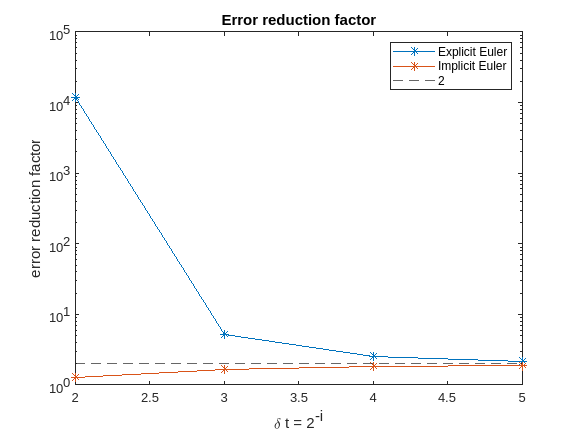

err_red_impl = approx_err_impl(1:end-1)./approx_err_impl(2:end);
err_red_expl = approx_err_expl(1:end-1)./approx_err_expl(2:end);
dt = 2:5;
figure
semilogy(dt,err_red_expl,'-*')
hold on
semilogy(dt,err_red_impl,'-*')
yline(2, '--')
hold off
title('Error reduction factor')
xlabel('\delta t = 2^{-i}')
ylabel('error reduction factor')
legend('Explicit Euler', 'Implicit Euler', '2')

**f)** In addition to accuracy, we examine an additional aspect of ‘quality’ of a method: the *stability*. Descriptively spoken, stability denotes the applicability of a method for varying parameters, whereas at least results similar to the exact/correct solution have to be achieved (In particular, unphysical oscillations should not occur).

With this heuristic definition, decide for which of the used values for $\delta t$ each of the examined methods is stable (in the case of our problem).

Mark stable cases by a cross in the last table. Try to find a simple criterion to determine whether a solution is stable or not and write the result to the MATLAB console as well.

**Hint:** It is **not** necessary to perform a von Neumann stability analysis here!

explicit_euler_table = table([1/2 approx_err_expl(1) nan]', [1/4 approx_err_expl(2) err_red_expl(1)]', [1/8 approx_err_expl(3) err_red_expl(2)]',...
    [1/16 approx_err_expl(4) err_red_expl(3)]', [1/32 approx_err_expl(5) err_red_expl(4)]','rownames', {'δt', 'error', 'error red.'}, 'VariableNames', {'1/2', '1/4', '1/8','1/16', '1/32'});
T = table(explicit_euler_table,'VariableNames',{'Explicit Euler'}); % Nested table
disp(T)

                              Explicit Euler                           
                   1/2        1/4        1/8        1/16        1/32   
    ___________________________________________________________________

    δt               0.5       0.25      0.125      0.0625      0.03125
    error         3290.5    0.27816    0.05391    0.021542    0.0099091
    error red.       NaN      11830     5.1597      2.5025        2.174



implicit_euler_table = table([1/2 approx_err_impl(1) nan]', [1/4 approx_err_impl(2) err_red_impl(1)]', [1/8 approx_err_impl(3) err_red_impl(2)]',...
    [1/16 approx_err_impl(4) err_red_impl(3)]', [1/32 approx_err_impl(5) err_red_impl(4)]','rownames', {'δt', 'error', 'error red.'}, 'VariableNames', {'1/2', '1/4', '1/8','1/16', '1/32'});
T = table(implicit_euler_table,'VariableNames',{'Implicit Euler'}); % Nested table
disp(T)

                                Implicit Euler                             
                    1/2         1/4         1/8         1/16        1/32   
    _______________________________________________________________________

    δt                 0.5        0.25       0.125      0.0625      0.03125
    error         0.062729    0.049302    0.030027    0.016529    0.0087114
    error red.         NaN      1.2724      1.6419      1.8166       1.8974



stable_cases_table = table(categorical(["1/2", "0", "X"])', categorical(["1/4", "0", "X"])', categorical(["1/8", "X", "X"])', categorical(["1/16", "X", "X"])', categorical(["1/32", "X", "X"])','rownames', ["δt", "Explicit Euler", "Implicit Euler"], 'VariableNames', {'1/2', '1/4', '1/8','1/16', '1/32'});
T = table(stable_cases_table,'VariableNames',{'Stable cases'}); % Nested table
disp(T)

                       Stable cases                    
                      1/2    1/4    1/8    1/16    1/32
    ___________________________________________________

    δt                1/2    1/4    1/8    1/16    1/32
    Explicit Euler    0      0      X      X       X   
    Implicit Euler    X      X      X      X       X   



Now for the **Van-der-Pol-Oscillator** we consider $\mu = 4$:

$\left\{ \begin{array}{l} \dot u = v \\ \dot v = 4(1-u^2)v-u \end{array} \right.$    (4)

with initial conditions

$\begin{array} {l} u(0) = 1 ,  \\ v(0) = 1 . \end{array} $    (5)

**g)** Try to solve the equation with the explicit Euler method. Use $t_{end} = 20$ and $\delta t = 0.1$. Note that you will have to extend your implementation to account for vector-valued functions. What do you observe?

*(N.B. implemented in a separate file)*

`function y = expl_euler(y_0, dt, t_end, f)`

`t = 0:dt:t_end;`

`y = zeros(length(y_0), length(t));`

`y(:,1) = y_0;`

`for n = 1:length(t)-1`

`    y(:,n+1) = y(:,n) + dt * f(y(:,n));`

`end`

`end`

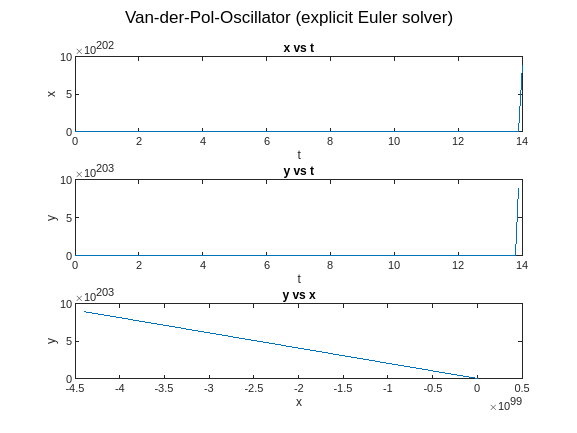

t_end = 20;
dt = .1;
mu = 4;
f = @(y) [y(2); mu*(1-y(1).^2).*y(2)-y(1)];
y_0 = [1; 1];
y = expl_euler(y_0, dt, t_end, f);
t = 0:dt:t_end;
figure
subplot(3,1,1)
plot (t,y(1,:))
xlabel('t')
ylabel('x')
title('x vs t')
subplot(3,1,2)
plot (t,y(2,:))
xlabel('t')
ylabel('y')
title('y vs t')
subplot(3,1,3)
plot (y(1,:),y(2,:))
xlabel('x')
ylabel('y')
title('y vs x')
sgtitle('Van-der-Pol-Oscillator (explicit Euler solver)')

**h)** Now extend your Newton Solver to vector-valued problems as well. Since the derivative is now a matrix (the Jacobian), use MATLAB’s builtin ‘\’ operator to solve the linear system.

**Hint:** Take care to replace 1 by the identity matrix where necessary.

*(N.B. implemented in a separate file)*

`function x=newton(x_0, G, dG)`

`maxI=100;`

`minEps=10e-8;`

`i=0;`

`epsilon=inf;`

`while(i<maxI && epsilon>minEps)`

`    inv_dG = dG(x_0)\eye(length(x_0));`

`    x=x_0-inv_dG*G(x_0);`

`    epsilon=norm(x-x_0)./max(norm(x),1);`

`    x_0=x;`

`    i=i+1;`

`end`

`end`

**i)** Solve the Van-der-Pol-Oscillator with the implicit Euler method using the extended Newton solver. Note that you will have to extend the implicit method implementation as well in order to handle vector-valued functions. Use the same parameters as in **g)**. Plot your solutions as in the previous worksheet: $u$ vs. $t$, $v$ vs. $t$, and $v$ vs. $u$ as subplots in the same figure.

**Hint:** The Jacobian of the right-hand side is:


$$Df(u,v)=\left( \begin{array} {cc} 0 & 1 \\ -2\mu uv-1 & \mu(1-u^2)\end{array} \right)$$


*(N.B. implemented in a separate file)*

`function y = impl_euler(y_0, dt, t_end, f, df)`

`    t = 0:dt:t_end;`

`    y = zeros(length(y_0),length(t));`

`    y(:,1) = y_0;`

`    for i=1:length(t)-1`

`        G = @(x) dt*f(x)-x+y(:,i);`

`        dG = @(x) dt*df(x)-eye(length(y_0));`

`        y(:,i+1) = newton(y(:,i), G, dG);`

`    end`

`end`

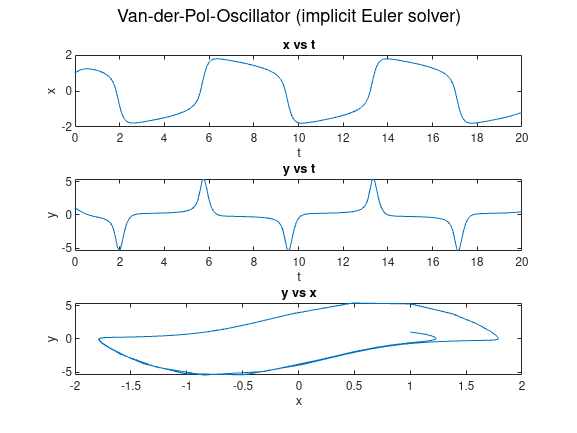

df = @(y) [0,                    1;
           -2.*mu.*y(1).*y(2)-1, mu.*(1-y(1).^2)];
y = impl_euler(y_0, dt, t_end, f, df);
figure
subplot(3,1,1)
plot (t,y(1,:))
xlabel('t')
ylabel('x')
title('x vs t')
subplot(3,1,2)
plot (t,y(2,:))
xlabel('t')
ylabel('y')
title('y vs t')
subplot(3,1,3)
plot (y(1,:),y(2,:))
xlabel('x')
ylabel('y')
title('y vs x')
sgtitle('Van-der-Pol-Oscillator (implicit Euler solver)')